# Fase 1: Análisis Estadístico Exploratorio 

#### *Clasificación Espectral de Objetos Astronómicos mediante Aprendizaje Automático: Aplicación al Dataset SDSS DR1*7 

### Mariana Castellanos

% Cargar datos
T = readtable('star_classification_original.csv');

% Inspección básica
head(T)          % primeras 8 filas

      obj_ID      alpha      delta        u         g         r         i         z       run_ID    rerun_ID    cam_col    field_ID    spec_obj_ID      class       redshift    plate     MJD     fiber_ID
    __________    ______    ________    ______    ______    ______    ______    ______    ______    ________    _______    ________    ___________    __________    ________    _____    _____    

size(T)          % filas y columnas

ans =       100000          18


summary(T)       % tipo de cada variable + estadísticas rápidas

Variables:

    obj_ID: 100000×1 double

        Values:

            Min       1.2376e+18
            Median    1.2377e+18
            Max       1.2377e+18

    alpha: 100000×1 double

        Values:

            Min       0.0055278
            Median        180.9
            Max             360

    delta: 100000×1 double

        Values:

            Min       -18.785 
            Median     23.646 
            Max        83.001 

    u: 100000×1 double

        Values:

            Min         -9999 
            Median     22.179 
            Max        32.781 

    g: 100000×1 double

        Values:

            Min         -9999 
            Median       21.1 
            Max        31.602 

    r: 100000×1 double

        Values:

            Min        9.8221 
            Median     20.125 
            Max        29.572 

    i: 100000×1 double

        Value

El dataset SDSS DR17 objeto de estudio comprende 17 variables descriptivas por observación, que pueden clasificarse en cuatro categorías funcionales: identificadores únicos, coordenadas celestes, mediciones fotométricas/espectroscópicas, y metadatos instrumentales.

Las variables de mayor relevancia para la clasificación automática son las cinco magnitudes fotométricas (u, g, r, i, z) y el redshift (redshift), dado que encapsulan la información física fundamental sobre la naturaleza de los objetos astronómicos. Las variables de identificación y metadatos, aunque esenciales para la trazabilidad y el control de calidad, típicamente no se emplean como predictores directos en modelos de clasificación.

## Balance de datos

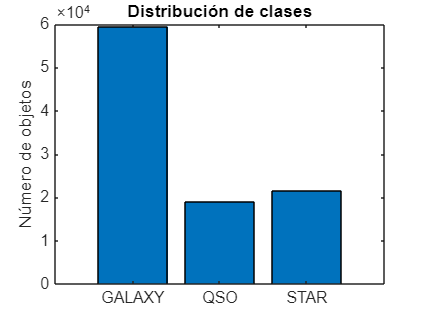

%% Conteo por clase
clases = T.class;
categorias = unique(clases);
conteos = countcats(categorical(clases));  % o tabulate(clases)

% Visualización
figure;
bar(categorical(categorias), conteos);
title('Distribución de clases');
ylabel('Número de objetos');

El dataset SDSS DR17 presenta un desbalance de clases moderado pero estadísticamente relevante. Las galaxias constituyen la clase mayoritaria con 59.445 observaciones (59,4% del total), mientras que las estrellas y los cuásares representan el 21,6% (21.594) y el 19,0% (18.961), respectivamente, sobre un total de 100.000 registros.

Este desbalance tiene implicaciones directas sobre el diseño del clasificador. Un modelo entrenado sin corrección podría sesgarse hacia la clase GALAXY al optimizar la exactitud global (accuracy), ya que clasificar todos los objetos como galaxias daría trivialmente un 59,4% de acierto. Por esta razón, *métricas como el F1-score por clase y el recall para QSO y STAR serán los indicadores principales de desempeño en la Fase 3*. 

## Calidad de datos

%% Valores faltantes
sum(ismissing(T))  % por columna

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Valores centinela -9999 (común en astronomía)
vars_num = {'u','g','r','i','z','redshift'};
for k = 1:numel(vars_num)
    col = T.(vars_num{k});
    fprintf('%s: %d valores -9999\n', vars_num{k}, sum(col == -9999));
end

u: 1 valores -9999
g: 1 valores -9999
r: 0 valores -9999
i: 0 valores -9999
z: 1 valores -9999
redshift: 0 valores -9999



% Duplicados por spec_obj_ID
[~, idx_unicos] = unique(T.spec_obj_ID);
fprintf('Duplicados: %d\n', height(T) - numel(idx_unicos));

Duplicados: 0


La inspección de valores centinela (-9999, convención estándar en catálogos astronómicos para datos no disponibles) revela una contaminación mínima: un único registro afectado en cada uno de los filtros u, g y z, sin ninguna afección en los filtros r, i ni en el redshift. No se detectaron valores NaN adicionales.Aunque tres observaciones con valores centinela parecen anecdóticas frente a 100.000 registros, su presencia en los filtros u, g y z —precisamente las bandas con mayor utilidad discriminativa para cuásares y estrellas calientes— sugiere que estos registros podrían introducir ruido en regiones críticas del espacio de características. 

## Análisis univariado y bivariado 

### Estadísticas descriptivas por clase:

%% Separar por clase
idx_star   = strcmp(T.class, 'STAR');
idx_gal    = strcmp(T.class, 'GALAXY');
idx_qso    = strcmp(T.class, 'QSO');

### **Histogramas por variable y clase** (para u, g, r, i, z, redshift)

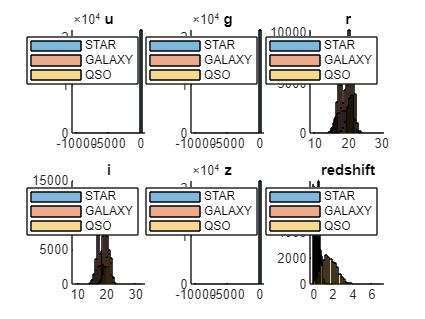

figure;
for k = 1:numel(vars_num)
    subplot(2,3,k);
    hold on;
    histogram(T.(vars_num{k})(idx_star),  30, 'FaceAlpha', 0.5);
    histogram(T.(vars_num{k})(idx_gal),   30, 'FaceAlpha', 0.5);
    histogram(T.(vars_num{k})(idx_qso),   30, 'FaceAlpha', 0.5);
    title(vars_num{k}); legend('STAR','GALAXY','QSO');
end

Los histogramas revelan un patrón estructural muy informativo: los filtros u y z muestran distribuciones concentradas en torno a cero, lo que evidencia que esos registros son los valores centinela (-9999) detectados en la sección anterior. Esto confirma que las tres observaciones problemáticas distorsionan la escala del eje X y deben eliminarse antes del modelado para que los histogramas sean interpretables en esas bandas.

En los filtros r e i, donde la escala no está distorsionada, se observa que las tres clases comparten un rango de magnitudes superpuesto (aproximadamente 14–25 mag), lo que implica que n*inguna de estas bandas tomada de forma individual es suficiente para separar las clases*. Sin embargo, las galaxias muestran una distribución que se extiende hacia magnitudes más débiles (valores numéricos más altos en la escala astronómica), consistente con que son objetos extendidos más difusos que estrellas puntuales a distancias comparables.

El redshift es la variable con mayor poder discriminativo individual. Las estrellas se concentran prácticamente en z ≈ 0 (objetos del vecindario galáctico, sin expansión cosmológica detectable), las galaxias presentan una distribución que se extiende hasta z ≈ 1,3 con una mediana alrededor de 0,4–0,5, y los cuásares alcanzan valores de hasta z > 5, reflejando que son los objetos más lejanos del catálogo. Esta separación hace del ***redshift el predictor más valioso para el clasificador***, aunque introducirlo directamente plantea un debate metodológico: en la práctica observacional, el redshift se mide espectroscópicamente, mientras que el sistema SDSS fotométrico solo lo estima indirectamente. Para un clasificador fotométrico puro, sería válido excluirlo y estudiar cuánto se degrada el desempeño.

### Boxplots **de redshift por clase**

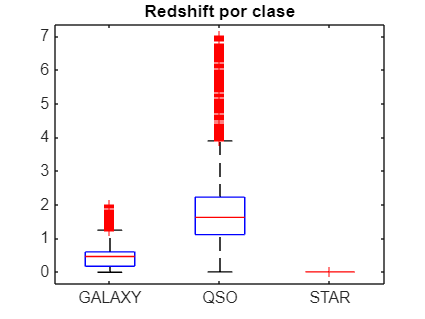

figure;
boxplot(T.redshift, T.class);
title('Redshift por clase');

El boxplot confirma y cuantifica la separación entre clases observada en los histogramas. Las estrellas presentan una caja prácticamente colapsada en z ≈ 0, con un rango intercuartílico (IQR) casi nulo, lo que físicamente es coherente: las estrellas de la Vía Láctea no participan de la expansión del universo. Las galaxias muestran una mediana cercana a 0,45 con un IQR de aproximadamente 0,0–0,65, mientras que los cuásares tienen una mediana alrededor de 1,6 y un IQR que se extiende hasta ~3,9, con numerosos valores atípicos por encima de 4.

Los outliers en GALAXY (valores de redshift > 1,3) y en QSO (valores > 4) no son errores de medición: son objetos reales en los extremos de la distribución cosmológica. Sin embargo, desde la perspectiva del clasificador, estas regiones de alto redshift representan zonas de fácil separación entre clases, mientras que la zona de solapamiento entre GALAXY y QSO en el rango z ≈ 0,8–1,3 será la región más difícil de clasificar correctamente. *Esta zona de ambigüedad es candidata a producir la mayor cantidad de errores en la matriz de confusión de la Fase 3.*

### Matriz de correlación

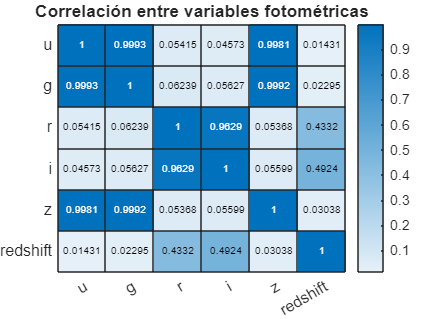

datos_num = table2array(T(:, vars_num));
figure;
heatmap(vars_num, vars_num, corr(datos_num, 'rows','complete'));
title('Correlación entre variables fotométricas');

La matriz de correlación expone dos bloques de alta correlación completamente desconectados entre sí, lo que tiene una interpretación física directa y consecuencias prácticas para el modelado.

El primer bloque lo conforman los filtros u, g y z, con correlaciones de 0,999 entre ellos. El segundo bloque lo forman los filtros r e i, con una correlación de 0,963. Entre ambos bloques, las correlaciones son prácticamente nulas (~0,05). Esta estructura no es un artefacto estadístico: *refleja que los filtros u, g y z capturan longitudes de onda en el extremo azul-ultravioleta y el infrarrojo lejano del sistema SDSS*, cuya variabilidad es dominada por los mismos procesos físicos (temperatura superficial y emisión UV en estrellas calientes, o la emisión de cuásares), mientras que *r e i cubren la franja óptica-roja media, sensible a poblaciones estelares más frías* y a la componente estelar evolucionada de las galaxias.

**Para el diseño del clasificador esto implica que incluir los cinco filtros fotométricos introduce redundancia severa**. Técnicamente, tres de las cinco magnitudes son casi linealmente dependientes de las otras, lo que puede inflar artificialmente la importancia de esas variables en modelos basados en distancias o en regresión. Una estrategia recomendable antes de la Fase 2 sería construir los colores diferenciales (u−g, g−r, r−i, i−z) en lugar de usar las magnitudes absolutas, ya que los colores capturan la forma del espectro de energía (SED) independientemente del brillo intrínseco del objeto, y tienen menor correlación entre sí.Finalmente, el redshift muestra correlaciones moderadas únicamente con r (0,43) e i (0,49), y valores cercanos a cero con el resto.* Esto indica que el redshift aporta información sustancialmente independiente de las magnitudes fotométricas*, reforzando su valor como predictor complementario dentro del modelo.

## Diagrama color-color 

#### ¿Qué es el diagrama color-color?

El diagrama color-color es una representación del espacio fotométrico en la que cada eje corresponde a la diferencia de magnitud entre dos filtros adyacentes —en este caso (u−g) en el eje X y (g−r) en el eje Y—. A diferencia de trabajar con magnitudes absolutas, los colores diferenciales son independientes de la distancia al objeto y del brillo intrínseco, de modo que codifican únicamente la forma del espectro de energía distribuida (SED). Esto los convierte en huellas espectrales de baja resolución: cada tipo de objeto astronómico ocupa una región característica del plano color-color.

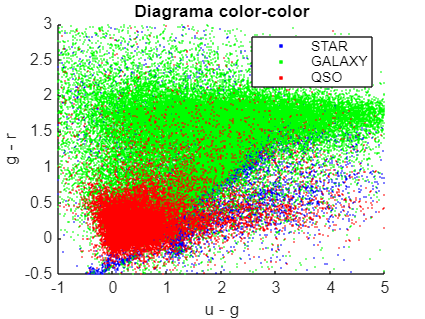

u_g = T.u - T.g;
g_r = T.g - T.r;

figure; hold on;
scatter(u_g(idx_star), g_r(idx_star), 5, 'b', '.');
scatter(u_g(idx_gal),  g_r(idx_gal),  5, 'g', '.');
scatter(u_g(idx_qso),  g_r(idx_qso),  5, 'r', '.');
xlim([-1 5]);
ylim([-0.5 3]);
xlabel('u - g'); ylabel('g - r');
title('Diagrama color-color'); legend('STAR','GALAXY','QSO');

El diagrama muestra tres poblaciones con distribuciones espaciales parcialmente distinguibles. Las estrellas (azul) forman una secuencia diagonal compacta con valores de (u−g) entre aproximadamente −1 y 2, y (g−r) entre −0,5 y 0,5. Esta estructura estrecha es la denominada secuencia principal estelar en el espacio color-color, y su compacidad refleja que la emisión térmica de las estrellas sigue una relación física bien definida entre colores adyacentes.

Los cuásares (rojo) se concentran en la región de valores (u−g) negativos a moderados y (g−r) cercano a cero, generalmente por debajo de la secuencia estelar. Esta posición es consecuencia de la emisión no térmica de los núcleos activos, que produce un exceso en el ultravioleta (filtro u) respecto a lo esperado para una estrella de temperatura equivalente.

Las galaxias (verde) presentan la dispersión más amplia, extendiéndose hacia valores positivos de ambos colores. Esto refleja su naturaleza como sistemas compuestos: las galaxias con poblaciones estelares envejecidas son más rojas (mayor g−r), mientras que las galaxias con formación estelar activa tienen colores más azules y se superponen con la región de las estrellas.

La separación entre cuásares y estrellas es razonablemente clara, pero el solapamiento entre galaxias y las otras dos clases indica *que el diagrama color-color por sí solo no es suficiente para un clasificador robusto*: el redshift y posiblemente los colores r−i e i−z serán necesarios para resolver las ambigüedades.

## Conclusiones de la Fase 1 e Implicaciones para la Fase 2

El análisis estadístico exploratorio permite extraer las siguientes conclusiones, ordenadas por su relevancia para el diseño del clasificador en la Fase 2:

- **El redshift es el predictor dominante**. Es la única variable que, por sí sola, separa limpiamente las tres clases estrellas en z ≈ 0, galaxias en z ∈ [0, 1,3] y cuásares en z ∈ [0,5, 7]. Su inclusión como predictor mejorará sustancialmente el desempeño de cualquier clasificador. Sin embargo, dado que en astronomía observacional el redshift espectroscópico requiere tiempo de telescopio adicional, podría ser de interés evaluar también un clasificador fotométrico puro (sin redshift) para cuantificar la degradación de desempeño.

- **Las magnitudes fotométricas brutas son altamente redundantes**.Los dos bloques de correlación $\{u, g, z\}$ ($\rho \geq 0{,}998$) y $\{r, i\}$ ($\rho = 0{,}963$) implican que incluir las cinco magnitudes como predictores independientes inflaría artificialmente la dimensionalidad sin aportar información nueva. Se recomienda sustituirlas por los cuatro colores diferenciales ($u-g$, $g-r$, $r-i$, $i-z$) antes de entrenar los modelos. 

- **El desbalance de clases exige estrategias de mitigación**. La razón de 59,4 % GALAXY frente a ∼20 % de cada clase minoritaria impone el uso de validación cruzada estratificada y métricas por clase (F1-score, recall) como criterios de selección del modelo. Los clasificadores basados en probabilidad (p.ej., Naïve Bayes o regresión logística multinomial) permiten además ajustar umbrales de decisión por clase, lo que los hace especialmente adecuados para este escenario.

- **La zona de mayor dificultad es GALAXY–QSO en z ≈ 0,8–1,3**. En esta región los colores fotométricos se solapan y el redshift no proporciona separación clara. Los errores de clasificación se concentrarán aquí; el análisis de la matriz de confusión de la Fase 3 deberá prestar atención específica a este par de clases.

- **Limpieza previa al entrenamiento**. Los tres registros con valores centinela en u, g y z deben eliminarse antes de construir los modelos. Su presencia es anecdótica en volumen pero puede introducir ruido en una región crítica del espacio de características para la separación de cuásares.